## Problema 3

A column is made of a certain material with Young modulus $R = 181\times 10^{6}\, \text{kN/m}^{2}$ The geometry of the column is shown in the figure. We wish to analyze the column for displacements using the FEM.

                                            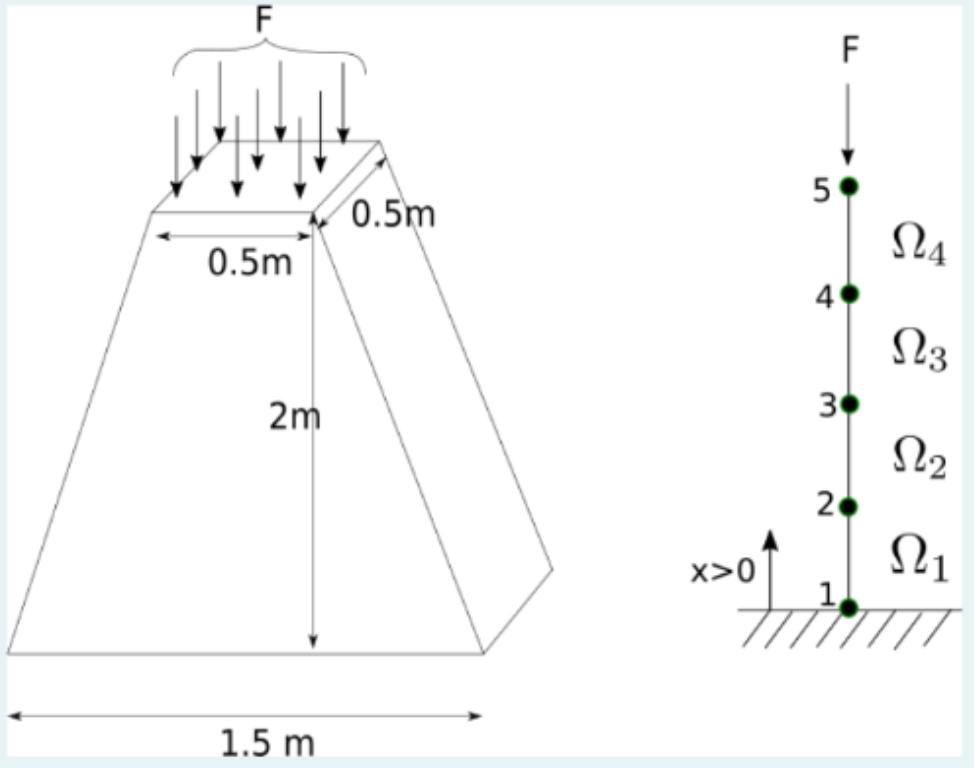

The column is indeed a three-dimensional structure. However, we wish to approximate the column as one dimensional. To this end, we represent the distributed force at the top of the column as a point force $F = 5\, \text{kN}$.

    The weight of the material is represented by the body force per unit lenght: $f(x) = -6.25 (3 - x)\ \text{kN/m}$. The governing differential equation for the problem is given by $-\frac{\mathrm{d}}{\mathrm{d} x}\left(E A(x) \frac{\mathrm{d} u}{\mathrm{d} x}\right) = f(x)$ where $A(x)$ is the cross-sectional area.

    Consider a mesh with $4$ linear elements of equal length $h = 0.5\ \text{m}$.

(a) *(3 points)* The value $K_{2,3}$ of the stiffness matrix is:

- Empty answer (no penalty)

- 
$$\texttt{-2.0362e+08}\ \text{m}$$


- 
$$\texttt{-1.8326e+08}\ \text{m}$$


- 
$$\texttt{-2.2806e+08}\ \text{m}$$


- 
$$\texttt{-2.2602e+08}\ \text{m}$$


clearvars
close all

%E = 1.81e8; %kN/m^2 
%ff = 5.0;   %kN

syms x x1 x2 E alpha beta

%alpha = -3 /4; beta = 1 / 4;

A = @(x) alpha * x + beta;

Psi = @(x,x1,x2) [(x-x2)/(x1-x2); (x-x1)/(x2-x1)];
Ke = @(x, x1, x2, E, alpha, beta) E*int(A(x) * diff(Psi(x,x1,x2),x)*diff(Psi(x,x1,x2),x)',x,x1,x2);

Ke(x, x1, x2, E, alpha, beta) Solution

$$ans = \left(\begin{array}{cc} \text{E}\,\left(\frac{\alpha }{2}-\frac{\beta +\alpha \,x_{1}}{x_{1}-x_{2}}\right) & \text{E}\,\left(\frac{\alpha }{2}+\frac{\beta +\alpha \,x_{2}}{x_{1}-x_{2}}\right)\\ \text{E}\,\left(\frac{\alpha }{2}+\frac{\beta +\alpha \,x_{2}}{x_{1}-x_{2}}\right) & \text{E}\,\left(\frac{\alpha }{2}-\frac{\beta +\alpha \,x_{1}}{x_{1}-x_{2}}\right) \end{array}\right)$$

### Solution

#### Formulae

Shape functions of  the linear 1D element $\Omega^{e}$:

                                        
$$\psi^{e}_{1}(x) = \frac{x-x^{e}_{2}}{x^{e}_{1} - x^{e}_{2}},\qquad\qquad
\psi^{e}_{2}(x) = \frac{x-x^{e}_{1}}{x^{e}_{2} - x^{e}_{1}}.\qquad\qquad
$$


Components of the local stiffness matrix. $\displaystyle K^{e}_{i,j} = \int_{x^{e}_{1}}^{x^{e}_{2}} a_{1}(x) \frac{\mathrm{d}\psi^{e}_{i}}{\mathrm{d} x}(x) \frac{\mathrm{d}\psi^{e}_{j}}{\mathrm{d} x}(x)\; \mathrm{d} x$. In this case in point, $a_{1}(x) = E A(x)$, and the sectional area changes linearly with the height $x$, so we can write $A(x) = \alpha x + \beta$. As $A(0) = 


$$

$$K^{e} = \left(\begin{array}{cc}
\textrm{E}\,{\left(\frac{\alpha }{2}-\frac{\beta +\alpha \,x_1 }{x_1 -x_2 }\right)} & \textrm{E}\,{\left(\frac{\alpha }{2}+\frac{\beta +\alpha \,x_2 }{x_1 -x_2 }\right)}\\
\textrm{E}\,{\left(\frac{\alpha }{2}+\frac{\beta +\alpha \,x_2 }{x_1 -x_2 }\right)} & \textrm{E}\,{\left(\frac{\alpha }{2}-\frac{\beta +\alpha \,x_1 }{x_1 -x_2 }\right)}
\end{array}\right)$$$$





elem = [1, 2;
    2, 3;
    3, 4;
    4, 5];

h = 0.5;

nodes = [0:h:2]';

numElem = size(elem,1);
numNodes = size(nodes,1);

A(x) = 3/4 - x / 4;

Error using indexing (line 923)
Invalid MATLAB indexing or symbolic function definition. Symbolic function arguments must be symbolic variables and function body must be convertible to sym expression.

Related documentation

f(x) = -6.25 * (3 - x);

K = zeros(numNodes);
F = zeros(numNodes,1);
Q = zeros(numNodes,1);

for e = 1:numElem
    rows = [elem(e,1), elem(e,2)];
    cols = rows;
    x1 = nodes(rows(1)); x2 = nodes(rows(2));
    Ke = E*int(A(x) * diff(Psi(x,x1,x2),x)*diff(Psi(x,x1,x2),x)',x,x1,x2);
    Fe = int(f(x) * Psi(x,x1,x2),x,x1,x2);
    K(rows,cols) = K(rows,cols) + Ke;
    F(rows) = F(rows) + Fe;
end
   
fprintf("(a) K(2,3) = %.4e m\n",K(2,3))
%Fixed Nodes
fixedNods = 1;
freeNods = setdiff(1:numNodes, fixedNods);

%Boundary Conditions
% Natural B.C.
Q(5) = -ff;
%Essential B.C
u = zeros(numNodes,1);
u(1) = 0.0;

%Reduced system
Km = K(freeNods,freeNods);
Fm = F(freeNods) + Q(freeNods) - K(freeNods,fixedNods)*u(fixedNods);

%Solution of the reduced system
u(freeNods) = Km \ Fm; 

fprintf("(b) Approximate soluiton at x = 2: u_approx(2) = %.4e m\n", u(end))
fprintf("Hint: The approximate solution at x = 1 is u_approx(1) = %.4e m\n", u(3))
% Elongation of the last element
elongation = u(5) - u(4);
fprintf("Elongation of the last element: %.4e m\n", elongation)
